load('AnalogData.mat');
rawData = out.AnalogData

rawData =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


Nround = 21;
Nsample = 2001;

% Manipulate matrix
distanceData = rawData(:, 1)

distanceData =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


analogs = rawData(:, 2)

analogs =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


anaData = reshape(analogs, [Nsample, Nround])'

anaData =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    10     2     1     7     8    12     7     7     8     3     7     8     5     6     8     6     5     7     6     4     8     7     7     5     7     7     6     6     7     6     7     8     7     7     5     7     8     6     8     8     7     7    13     7    11    10     7     6     4     7
    73    72    72    75    72    68    77    74    72    72    69    73    75    72   


% to be used
anaData = cast(anaData, "double");
voltData = anaData .* 3.3 ./ 4096.0

voltData =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        


meanVoltDataVSRef = ((mean(voltData, 2)/3.3) *100)

meanVoltDataVSRef =          0
         0
    0.1693
    1.7735
    3.4110
    4.9742
    6.5603
    8.1384
    9.6822
   11.2467


measureX = 0 : 5 : 100

measureX =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100


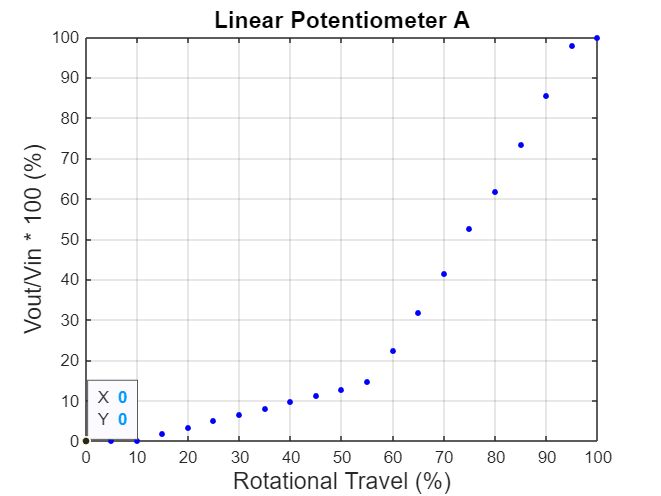

% Plotting
measureGraph = plot(measureX, meanVoltDataVSRef, 'o', 'MarkerSize', 3, 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');
% Add on
xticks(0:10:100);
xticklabels(0:10:100);
datatip(measureGraph);
grid on;
title('Linear Potentiometer A', 'FontSize', 14);
xlabel('Rotational Travel (%)', 'FontSize', 14); 
ylabel('Vout/Vin * 100 (%)', 'FontSize', 14); 

% Load PlotData
load('linearA.mat');
load('x.mat');

% Read and plot datasheet
datasheetValue = linearA

datasheetValue =     0.3600    0.5300    0.8300    1.8500    2.4600    3.9700    5.8600    8.2500   10.9000   13.1600   15.4300   18.3200   22.8600   30.0400   40.2400   51.8300   64.5500   76.0000   89.0000  100.0000  100.0000


datasheetX = x;

% Calculate Errors
err = 20/100 * datasheetValue

err =     0.0720    0.1060    0.1660    0.3700    0.4920    0.7940    1.1720    1.6500    2.1800    2.6320    3.0860    3.6640    4.5720    6.0080    8.0480   10.3660   12.9100   15.2000   17.8000   20.0000   20.0000


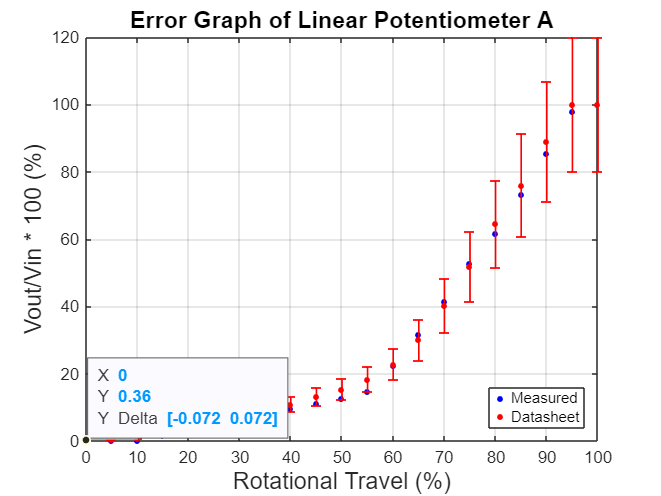

% Plotting Graph
measureGraph;
hold on;
datasheetGraph = plot(datasheetX, datasheetValue, 'o', 'MarkerSize', 3, 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r');
errorGraph = errorbar(measureX, datasheetValue, err, 'or', 'LineWidth', 1, 'MarkerSize', 1, 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r'); 
hold off;
% Add on
datatip(measureGraph);
datatip(datasheetGraph);
datatip(errorGraph);
xticks(0:10:100);
xticklabels(0:10:100);
grid on;
title('Error Graph of Linear Potentiometer A', 'FontSize', 14);
xlabel('Rotational Travel (%)', 'FontSize', 14); 
ylabel('Vout/Vin * 100 (%)', 'FontSize', 14); 
legend('Measured', 'Datasheet', 'Location', 'southeast');